% % getting whole group workflow (up til now) together

% add path to functions/scripts
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\KC_thresh_functions

% load individual vars into group cell arrays
[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupIdxSmallPupilTrials, groupIdxLargePupilTrials, groupLongAxis, groupMeanPupilDiameterAllTrials, groupRunThresh, groupPupThresh] = makeGroupStruct();
% of no pup data:
%[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupRunThresh] = makeGroupStruct_noPup();

% get stim conditions in order of trial & list of stim params to loop thru
% (This needs to be done new w/in the loop too each sess since the order of trialCond matters.. right now it's jsut to define cont & durat etc)
n = 1;
[durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of fluorescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons

reigons =     'V1'    'LP-HVA'    'LA-HVA'    'MA-HVA'    'control'


cons4Legend

cons4Legend =     '0'    '0.03'    '0.0625'    '0.125'    '0.25'    '0.5'    '1'


durs4Legend 

durs4Legend =     '6'


% CRFs

% which areas/stimulus parameters to loop over:

n = 1; % this is just to get the number of points
visArea = 1:length(groupRoundXpts{1,n})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

%durat = 1:length(uniqueDurations)
durat = 1 % (durat = 1 means 100 ms in final set of expts)

durat = 1


cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7;

% LOCO NO PUP

% stat group CRF matrix
state = 'loRun'

state = loRun

clear loRun_allSessAllPtsAllDurs_CRF
[loRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% duration x contrasts x points x sessions
sizeloRunAllSessAllPtsAllDurs_CRF = size(loRun_allSessAllPtsAllDurs_CRF)

sizeloRunAllSessAllPtsAllDurs_CRF =      1     7     5     3


% run group CRF matrix
state = 'hiRun'

state = hiRun

clear hiRun_allSessAllPtsAllDurs_CRF
[hiRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRunAllSessAllPtsAllDurs_CRF = size(hiRun_allSessAllPtsAllDurs_CRF)

sizeHiRunAllSessAllPtsAllDurs_CRF =      1     7     5     3


% for crf figs
yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
x_axis = [1:length(uniqueContrasts)];
xMax = max(x_axis);
xMin = min(x_axis);
xLimit = [xMin xMax];

% PLOT locomotion CRF
stateLegend = {'stat','run'}

stateLegend =     'stat'    'run'


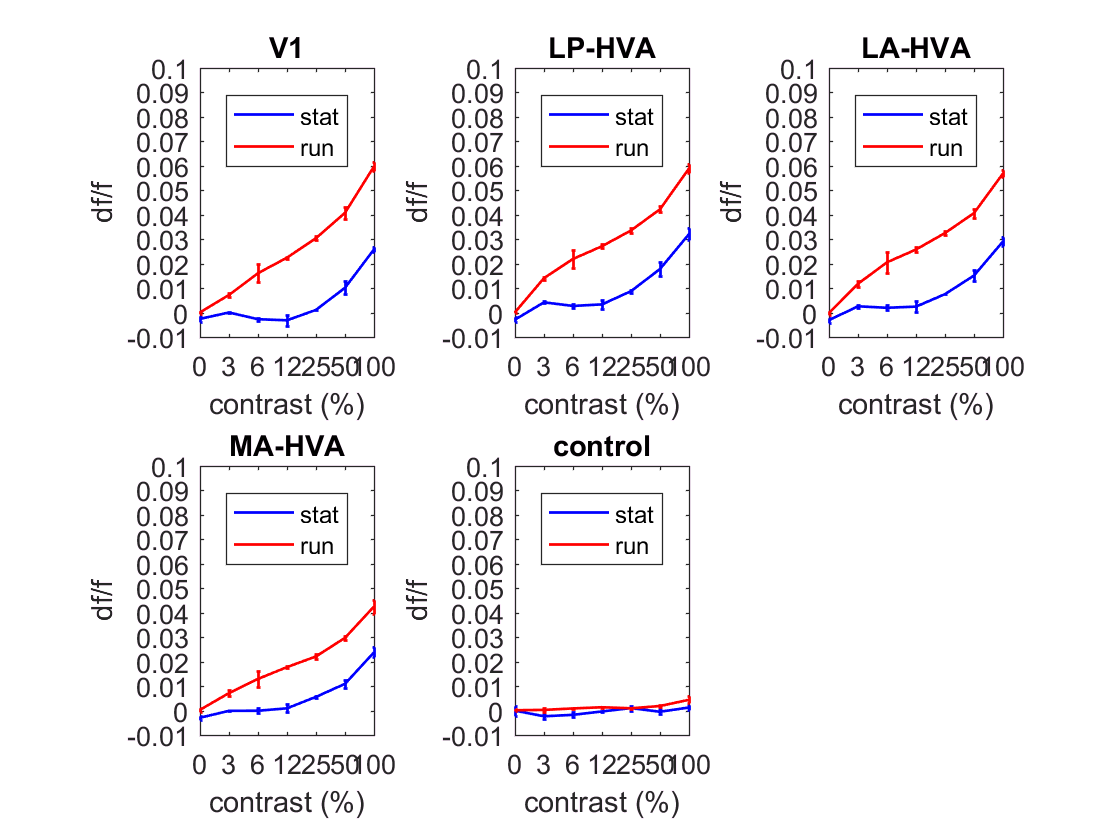

plotCompareBehState_CRF(loRun_allSessAllPtsAllDurs_CRF,hiRun_allSessAllPtsAllDurs_CRF,durat,yMax,yMin,yLimit,x_axis,xMax,xMin,xLimit,stateLegend,uniqueContrasts,reigons,nGroup);

% MEAN TRACE figs

state = 'loRun'
[loRun_mnTraceAllConsDursPts] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeLoRun_mnTraceAllConsDursPts = size(loRun_mnTraceAllConsDursPts)

state = 'hiRun'
[hiRun_mnTraceAllConsDursPts] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeHiRun_mnTraceAllConsDursPts = size(hiRun_mnTraceAllConsDursPts)

visArea = 1;
%visArea = 4;

%visArea = 1:length(groupRoundXpts{1,n})
durat = 1:length(uniqueDurations)
cont = 1:length(uniqueContrasts)

yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];

%x_axis = [1:length(uniqueContrasts)];
%xMax = max(x_axis);
%xMin = min(x_axis);
%xLimit = [xMin xMax];

% locomotion mean trace figs
stateLegend = {'stat','run'}
plotCompareBehState_mnTrace(loRun_mnTraceAllConsDursPts,hiRun_mnTraceAllConsDursPts,cons4axes,visArea,durat,cont,yMax,yMin,yLimit,stateLegend,nGroup)

% HISTOs - # trials also in this code...

% SESSIOn VARS

%durat = 1:length(uniqueDurations);
durat = 1

cont = 1:length(uniqueContrasts)
%cont = 7

visArea = 1:length(groupRoundYpts{1})
%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

sess = 1:nGroup

state = 'loRun'
[loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeLoRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial)
% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}

state = 'hiRun'
[hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial)
% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}

% both PLOT

%durat = 1:length(uniqueDurations);
durat = 1

cont = 1:length(uniqueContrasts)
%cont = 7

visArea = 1:length(groupRoundYpts{1})
%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3 % AL
%visArea = 4 % AM 
%visArea = 5 % control

sess = 1:nGroup
%sess = 1

yMax = 0.25
yLimit = [0 yMax]

xMax = 0.225
xMin = -0.1
xLimit = [xMin xMax]

xTickRange = [xMin:0.05:xMax]
xTickLabelRange = [xMin:0.05:xMax]

edgeWidth = 0.01
edges = [xMin xMin:edgeWidth:xMax xMax]
%numBins = 25;

durat = 1

cont =      1     2     3     4     5     6     7


visArea =      1     2     3     4     5


sess =      1     2     3


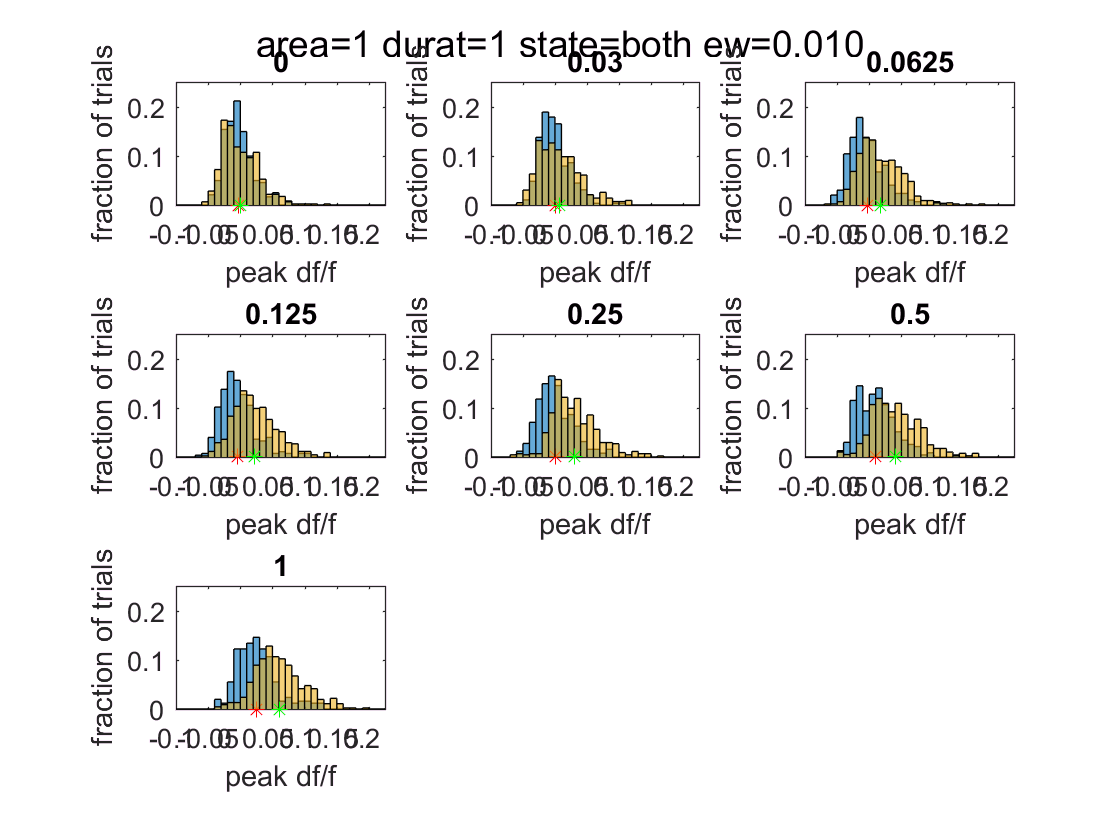

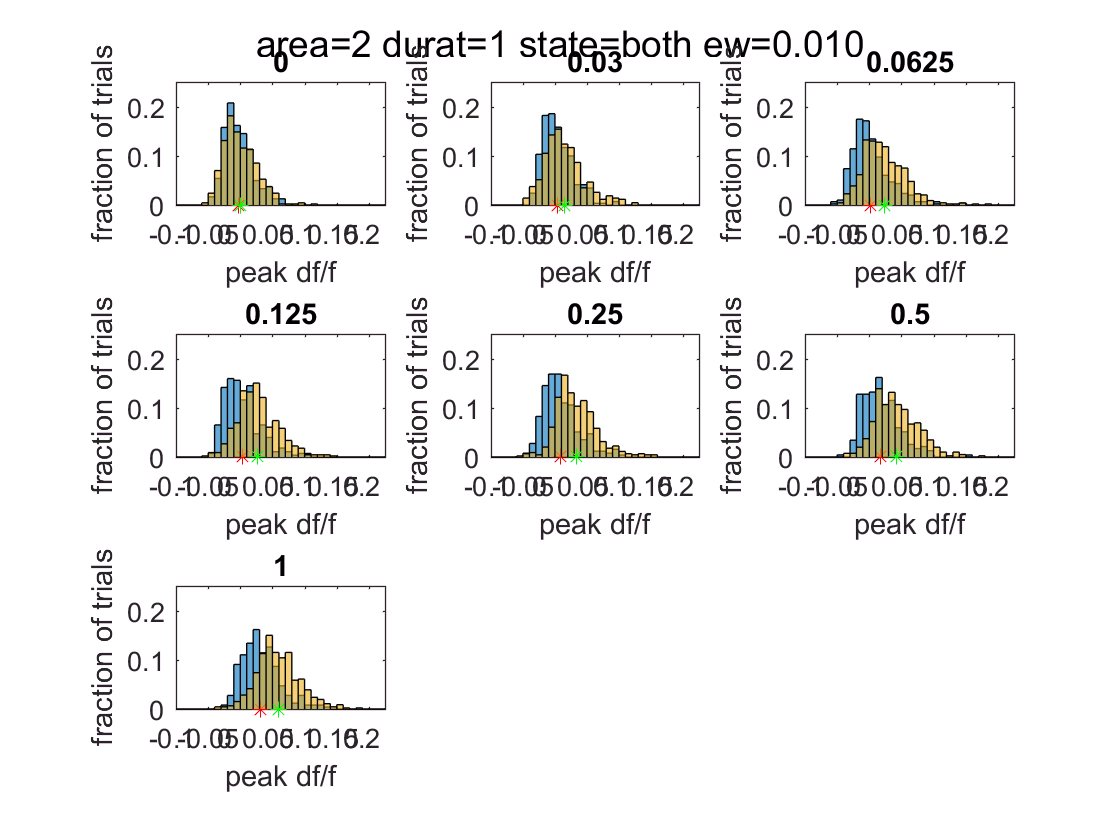

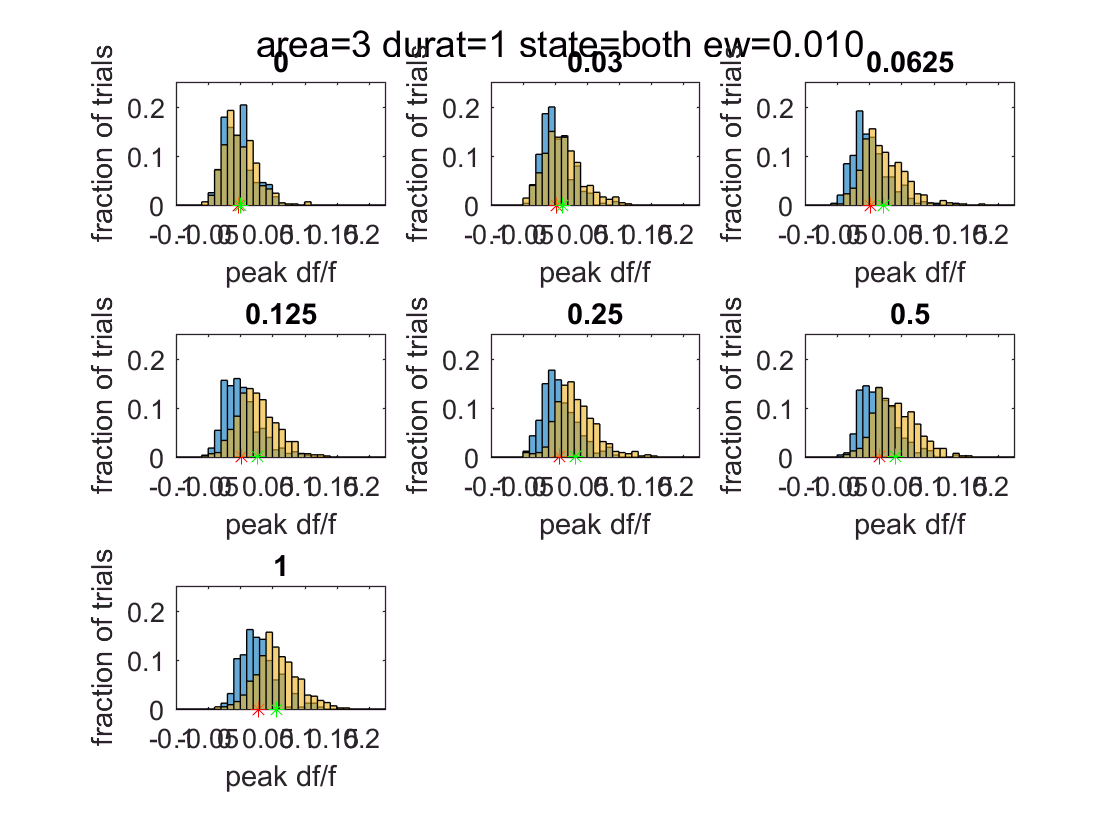

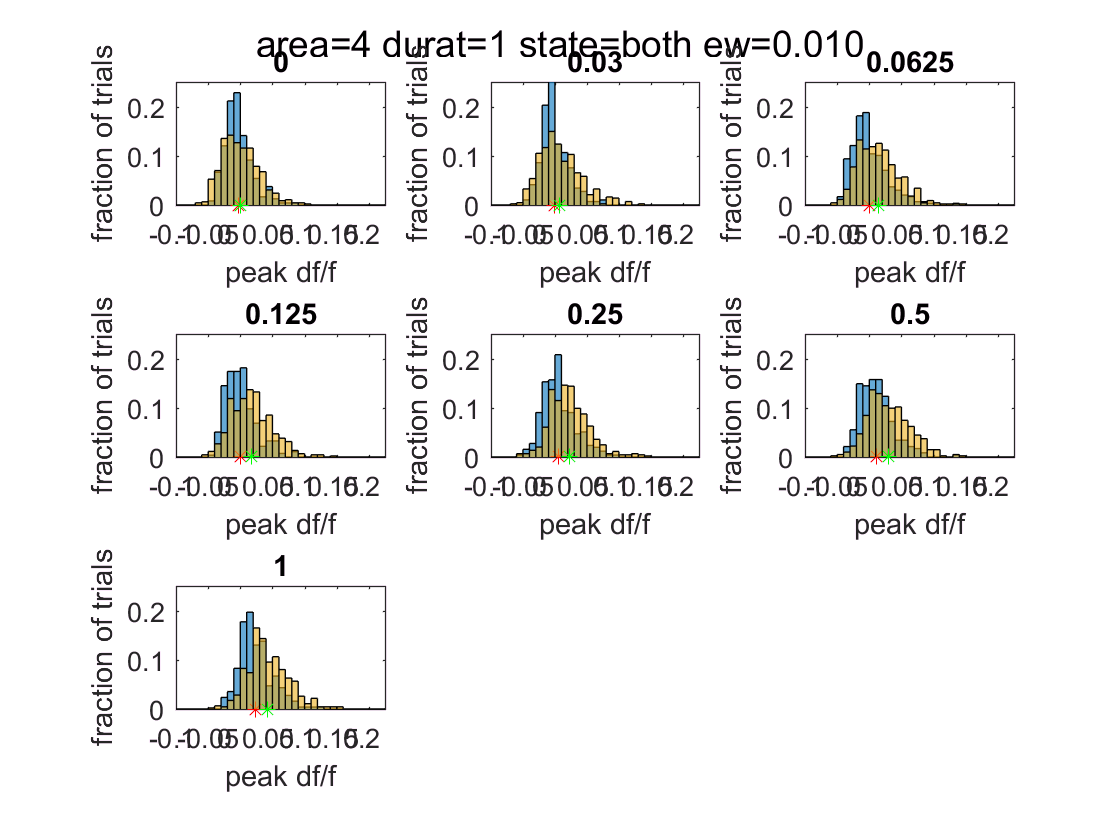

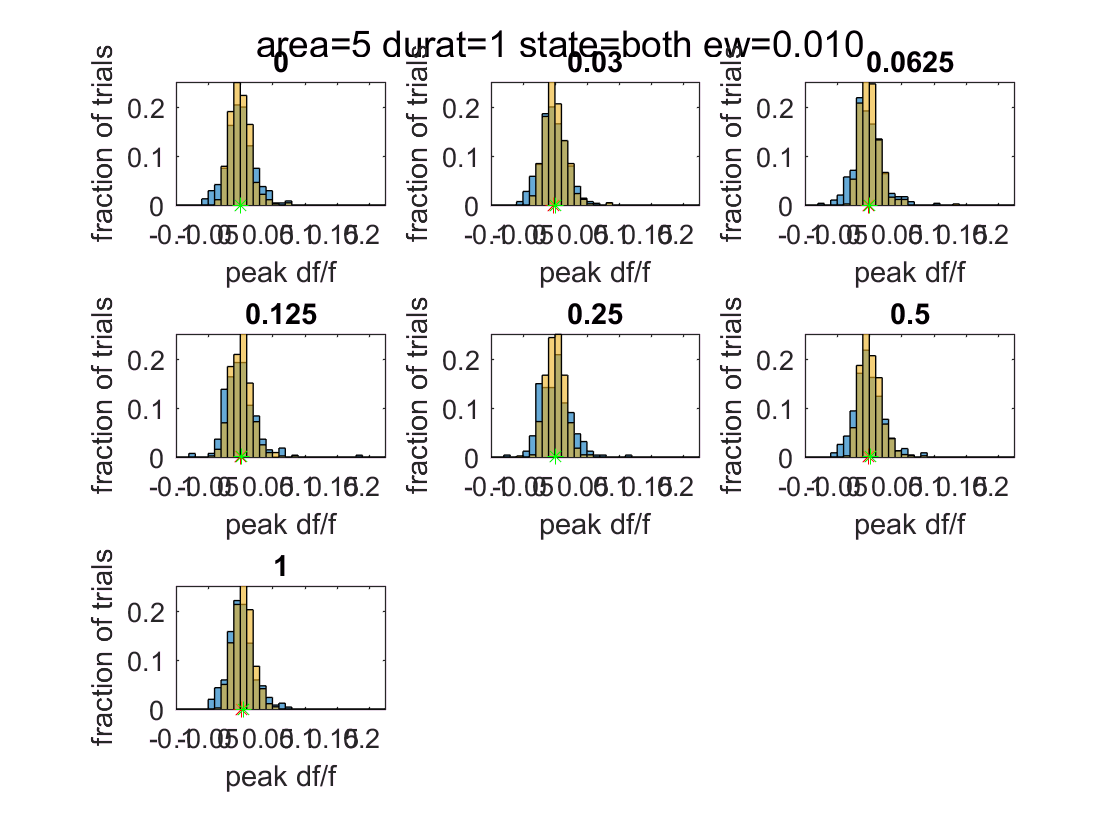

% HISTO FIGS & num TRIAL matricies

clear d
for d = durat
   
    clear i
    %visArea = 5;
    for i = visArea 
        
        fig2 = figure;
        
        state = 'both';
        %formatSpec = 'c=%s, mn=%0.3f, st=%0.3f, n=%1.0f';
        formatSpec = 'area=%1.0f durat=%1.0f state=%s ew=%0.3f'; % \n
        titleText = sprintf(formatSpec,i,d,state,edgeWidth);
        suptitle(titleText)
      
        clear lo_numTrialsAllSess_AllConsOnePt
        clear lo_sumTrialsAcrossSess_AllConsOnePt 
        
        clear lo_mnDf_allConsOnePt
        clear hi_mnDf_allConsOnePt
        
        clear lo_stderr_allConsOnePt
        clear hi_stderr_allConsOnePt
                 
        clear c
        for c = cont
            
            % emty matricies to add different number of trials to each time thru sessions loop (below)
            clear lo_dthithCthNth_pkDfEachTrial
            lo_dthithCthNth_pkDfEachTrial = []; 
        
            clear hi_dthithCthNth_pkDfEachTrial
            hi_dthithCthNth_pkDfEachTrial = [];
             
            clear n
            for n = sess
  
                % get values for *all* sesson, cth dth ith trials, lo state
                lo_dthithCthNth_pkDfEachTrial = [lo_dthithCthNth_pkDfEachTrial,loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                % for *nth* trial, cth contrast, save num of trials at this contrast
                % num trials this n this c
                lo_numTrialsAllSess_AllConsOnePt(n,c) = length(loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
                % get values for all sesson, cth dth ith trials, hi state
                hi_dthithCthNth_pkDfEachTrial = [hi_dthithCthNth_pkDfEachTrial,hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                % for nth trial, cth contrast, save num of trials at this contrast
                hi_numTrialsAllSess_AllConsOnePt(n,c) = length(hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
            end % end n loop - now have all mean peak df values for each trial, all sessions pooled
            % but for only 1 con
            
            % COLLECT  
            % save number of trials across all sessions for each contrast
            lo_sumTrialsAcrossSess_eachConOnePt = sum(lo_numTrialsAllSess_AllConsOnePt(:,c));
            % COLLECTING num trials across at sess for each contrast
            lo_sumTrialsAcrossSess_AllConsOnePt(1,c) = lo_sumTrialsAcrossSess_eachConOnePt;
            
            % PLOT LO STATE one con at a time, all sess at once, each subplot
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast  
            h1 = histogram(lo_dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            % CALC & COLLECT each MEAN Df across all sessions for cth con, ith point 
            lo_mnDf_eachConOnePt = mean(lo_dthithCthNth_pkDfEachTrial);
            % COLLECTING
            lo_mnDf_allConsOnePt(1,c) = lo_mnDf_eachConOnePt;
       
            y = 0;
            hold on
                
            % COLLECT
            lo_stderr_eachConOnePt = (std(lo_dthithCthNth_pkDfEachTrial))/(sqrt(length(lo_sumTrialsAcrossSess_eachConOnePt)));
            % COLLECTING
            lo_stderr_allConsOnePt(1,c) = lo_stderr_eachConOnePt;
            
            h2 = scatter(lo_mnDf_eachConOnePt,y,'*','r');
            %formatSpec = 'c=%s, mn=%0.3f, st=%0.3f, n=%1.0f';
            %title(sprintf(formatSpec,cons4axes{c},mnDf,stdev,lo_sumNumTrialsEachCon_allSess));
            title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            set(gca,'XTick',xTickRange)
            set(gca,'XTickLabel',xTickLabelRange)
            
            hold on
            
            % HI STATE PLOT
            
            % COLLECT
            % for each sess, cth contrast, save num of trials at this contrast
            hi_sumTrialsAcrossSess_eachConOnePt = sum(hi_numTrialsAllSess_AllConsOnePt(:,c));
            % COLLECTING
            hi_sumTrialsAcrossSess_AllConsOnePt(1,c) = hi_sumTrialsAcrossSess_eachConOnePt;
                   
            % PLOT one con at a time, all sess at once, each subplot
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))    
            h3 = histogram(hi_dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            % COLLECT
            hi_mnDf_eachConOnePt = mean(hi_dthithCthNth_pkDfEachTrial);
            % COLLECTING
            hi_mnDf_allConsOnePt(1,c) = hi_mnDf_eachConOnePt;

            y = 0;
        
            hold on
                
            % COLLECT
            hi_stderr_eachConOnePt = (std(hi_dthithCthNth_pkDfEachTrial))/(sqrt(hi_sumTrialsAcrossSess_eachConOnePt));
            % COLLECTING
            hi_stderr_allConsOnePt(1,c) = hi_stderr_eachConOnePt;
            
            h4 = scatter(hi_mnDf_eachConOnePt,y,'*','g');
            %formatSpec = 'c=%s, mnS=%0.3f, stS=%0.3f, \n mnR=%0.3f, stR=%0.3f nT=%1.0f,%1.0f';
            %title(sprintf(formatSpec,cons4axes{c},lo_mnDf_eachConOnePt,lo_stderr_eachConOnePt,hi_mnDf_eachConOnePt,hi_stderr_eachConOnePt,lo_sumTrialsAcrossSess_eachConOnePt,hi_sumTrialsAcrossSess_eachConOnePt));
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            set(gca,'XTick',xTickRange)
            set(gca,'XTickLabel',xTickLabelRange)
            
            
        end % end c loop

        % save num strials across *all* sess for each contrast amd each point
        % NOTE that num sess for each contrast will be the same across points...
        lo_sumTrialsAcrossSess_AllConsAllPts_notSqueezed(:,:,i) = lo_sumTrialsAcrossSess_AllConsOnePt;
        % squeeze, gives points x num trials per con across all sess (5 x 7)
        lo_sumTrialsAcrossSess_AllConsAllPts = squeeze(lo_sumTrialsAcrossSess_AllConsAllPts_notSqueezed)';
        % collecting num trials for *each* & all sess, con, point, & dur
        lo_numTrialsAllSess_AllConsAllPt(:,:,i) = lo_numTrialsAllSess_AllConsOnePt;
        % mean df all points/cons
        lo_mnDf_allConsAllPt(i,:) = lo_mnDf_allConsOnePt;
        % mean sterr all points/cons
        lo_stderr_allConsAllPt(i,:) = lo_stderr_allConsOnePt;
        
        % save num strials across *all* sess for each contrast amd each point
        % NOTE that num sess for each contrast will be the same across points...
        hi_sumTrialsAcrossSess_AllConsAllPts_notSqueezed(:,:,i) = hi_sumTrialsAcrossSess_AllConsOnePt;
        % squeeze, gives points x num trials per con across all sess (5 x 7)
        hi_sumTrialsAcrossSess_AllConsAllPts = squeeze(hi_sumTrialsAcrossSess_AllConsAllPts_notSqueezed)';
        % collecting num trials for *each* & all sess, con, point, & dur
        hi_numTrialsAllSess_AllConsAllPt(:,:,i) = hi_numTrialsAllSess_AllConsOnePt;
        % mean df all points/cons
        hi_mnDf_allConsAllPt(i,:) = hi_mnDf_allConsOnePt;
        % mean sterr all points/cons
        hi_stderr_allConsAllPt(i,:) = hi_stderr_allConsOnePt;
        

    end % end i loop

end % end d loop


% lo
% each sess
size(lo_numTrialsAllSess_AllConsAllPt)

ans =      3     7     5


% across sess
size(lo_sumTrialsAcrossSess_AllConsAllPts)

ans =      5     7


% mean each contrast, across sess
size(lo_mnDf_allConsAllPt)

ans =      5     7


% stderr each con across sess
size(lo_stderr_allConsAllPt)

ans =      5     7



% hi
% each sess
size(hi_numTrialsAllSess_AllConsAllPt)

ans =      3     7     5


% across sess
size(hi_sumTrialsAcrossSess_AllConsAllPts)

ans =      5     7


% mean each contrast, across sess
size(hi_mnDf_allConsAllPt)

ans =      5     7


% stderr each con across sess
size(hi_stderr_allConsAllPt)

ans =      5     7


% STATS

% here we use the ouput 'loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial' 
% from function 'Histo_byBehState_noPup', which is also used in 'groupHisto.mlx'

% 2 sample t test on trial vectors (lo vs hi state)

% picking an alpha value (correct for mult. comparisons)
n_cons = 7 % # contrasts 

n_cons = 7

denom = n_cons-1 % # comparisons

denom = 6

alf = 0.05/denom % bonferroni correction for multiple comparisons

alf = 0.0083

% for stats loop (cell below)

%durat = 1:length(uniqueDurations);
durat = 1

durat = 1


cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7

visArea = 1:length(groupRoundYpts{1})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3 % AL
%visArea = 4 % AM 
%visArea = 5 % control

sess = 1:nGroup

sess =      1     2     3


%sess = 1

% this code is similar to the histo code in that it gathers all trials across all sess for each con,
% but different in that
% it then performs a 2 sample t test and saves out the test statistics
% also the histo function saves all the trials as nested cell array, which I don't need here

clear h_p_cil_cih__tstats_AllPairs
clear tstats_AllPairs

clear h_p_cil_cih__tstats_AllPairs_AllPts
clear tstats_AllPairs_AllPts

clear h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs
clear tstats_AllPairs_AllPts_AllDurs

for d = durat
    
    for i = visArea
        
        %for c = 1
        for c = 1:length(uniqueContrasts)
            
            % get df for each trial vector across all sessions, one
            % contrast at a time
            
            clear lo_dthithCthNth_pkDfEachTrial
            lo_dthithCthNth_pkDfEachTrial = []; 
        
            clear hi_dthithCthNth_pkDfEachTrial
            hi_dthithCthNth_pkDfEachTrial = [];
                
            clear n
            for n = sess
  
                % get values for 1st sesson, cth dth ith trials
                lo_dthithCthNth_pkDfEachTrial = [lo_dthithCthNth_pkDfEachTrial,loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                
                hi_dthithCthNth_pkDfEachTrial = [hi_dthithCthNth_pkDfEachTrial,hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                
            end % end n loop - now have all mean peak df values for each trial, all sessions pooled
            % but for only 1 con

            %%subplot(2,4,c)
            
            % one con at a time at first
            %%cdfplot(hi_dthithCthNth_pkDfEachTrial)
            
            %%hold on
            
            %%cdfplot(lo_dthithCthNth_pkDfEachTrial)
              
            % T-TEST 92 sample) on hi vs lo distribution
            [h,p,ci,t_stats] = ttest2(lo_dthithCthNth_pkDfEachTrial,hi_dthithCthNth_pkDfEachTrial,'Alpha',alf);
            
            %%title(sprintf('c=%1.0f, va=%1.0f, h=%1.0f, p=%0.4f',c,i,h,p))
            
            %%axis square
            
            % COLLECT t-stat params
            h_p_cil_cih__tstats_AllPairs(1,c) = h;
            h_p_cil_cih__tstats_AllPairs(2,c) = p;
            h_p_cil_cih__tstats_AllPairs(3,c) = ci(1,1);
            h_p_cil_cih__tstats_AllPairs(4,c) = ci(1,2);
            tstats_AllPairs{1,c} = t_stats;

        end % end contrast loop
        
        % collect stats x contrast grid for each point
        h_p_cil_cih__tstats_AllPairs_AllPts(:,:,i) = h_p_cil_cih__tstats_AllPairs;
        tstats_AllPairs_AllPts{i,:} = tstats_AllPairs;
        
    end % end i loop
    
    h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs(:,:,:,d) = h_p_cil_cih__tstats_AllPairs_AllPts;
    tstats_AllPairs_AllPts_AllDurs{d,:} = tstats_AllPairs_AllPts;
    
end % end d loop

% stats param x comparison contrast x points
size(h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs)

ans =      4     7     5


size(tstats_AllPairs_AllPts_AllDurs)

ans =      1     1


% plot SIG STAR CRF based on ttest results

% which areas/stimulus parameters to loop over:

n = 1; % this is just to get the number of points
visArea = 1:length(groupRoundXpts{1,n})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

%durat = 1:length(uniqueDurations)
durat = 1 % (durat = 1 means 100 ms in final set of expts)

durat = 1


cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7;

% for crf figs
yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
x_axis = [1:length(uniqueContrasts)];
xMax = max(x_axis);
xMin = min(x_axis);
xLimit = [xMin xMax];

% PLOT CRFs lo & hi w/significance lines *DISt of TRIALS* 

figure

% for each duration
clear d
for d = durat
    
    % for each point
    clear i
    for i = visArea
        
        % Plot the CRF for LO beh state
        
        % make a sub plot
        subplot(2,4,i)
        
        % plot LO beh state CRF
        x_axis = 1:length(uniqueContrasts);
        %plot(x_axis,mnCRF_acrossSess_AllDurAllPts_loBehState(i,:),'b')
        errorbar(x_axis,loRun_mnCRF_acrossSess_AllDurAllPts(i,:),loRun_stdErrCRF_acrossSess_allPts(i,:),'-b','LineWidth',0.75) 

        hold on
        
        % plot HI beh state CRF
        %plot(x_axis,mnCRF_acrossSess_AllDurAllPts_hiBehState(i,:),'r')
        errorbar(x_axis,hiRun_mnCRF_acrossSess_AllDurAllPts(i,:),hiRun_stdErrCRF_acrossSess_allPts(i,:),'r','LineWidth',0.75)
            
       % legend(stateLegend)
        
        hold on
        
        % reset asterisk counter for each vis area/beh state:
        counter = 0; % once counter = 1, stop plotting asterisk
         
        % for LO beh state
        % for each comparison, if h ==1, overlay a star (colored)
        clear com
        for com = 1:length(loBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs)
            
            if counter == 0
            
                if loBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs(1,com,i) == 1
                
                    hold on
                    
                    %plot(com+1,loRun_mnCRF_acrossSess_AllDurAllPts(i,com+1),'b*','LineWidth',1.1)
                    
                    xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
                    %xt={'0'; '0.03' ; '0.06' ; '0.12' ; '0.25' ; '0.5'; '1'} ; 
                    set(gca,'xtick',1:7); 
                    set(gca,'xticklabel',xt);
                    
                    H=sigstar({{xt{1},xt{min(find(loBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs(1,:,i) == 1))+1}}});
                    set(H,'color','b')
                    
                    counter = counter + 1;
                
                end % end plot if statement
               
            end % end counter if statement
            
        end % end com loop
        
        % plot asterisk at c=0 df value
        %plot(1,mnCRF_acrossSess_AllDurAllPts_hiBehState(i,1),'r*')
        % make a line
        %y = mnCRF_acrossSess_AllDurAllPts_hiBehState(i,1);
        %line([0,5],[y,y])
        
        hold on
        
        % set counter to zero again for the hi beh state
        counter = 0;
        
        % for each comparison, if h ==1, overlay a star (colored)
        clear com
        for com = 1:length(hiBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs)
            
            if counter == 0
            
                if hiBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs(1,com,i) == 1
                
                    hold on
                    
                    %plot(com+1,hiRun_mnCRF_acrossSess_AllDurAllPts(i,com+1),'r*','LineWidth',1.1)
                    clear xt
                    xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
                    set(gca,'xtick',1:7); 
                    set(gca,'xticklabel',xt);

                    H=sigstar({{xt{1},xt{min(find(hiBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs(1,:,i) == 1))+1}}});
                    set(H,'color','r')
                    
                    %ylim(yLimit)
        
                    counter = counter + 1;
           
                end % end if statement
                
            end % end if statement
            
        end % end com loop
        
        title(reigons{i})
    
        ylim(yLimit) 
        xlim(xLimit)
    
        ylabel('df/f')
        xlabel('contrast (%)')
        
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        %xt={'0'; '0.03' ; '0.06' ; '0.12' ; '0.25' ; '0.5'; '1'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
    
        %yt = [-0.01 0 0.01 0.02 0.03 0.04 0.05 0.06 0.07 0.08 0.09];
        %yt = [-0.01 0 0.02 0.04 0.06 0.08];
        set(gca,'YTick',yt)
        
        axis square
        
    end % end i loop 
    
end % end d loop


% do ks test

% plot h, p, and vert lines on cdf plot